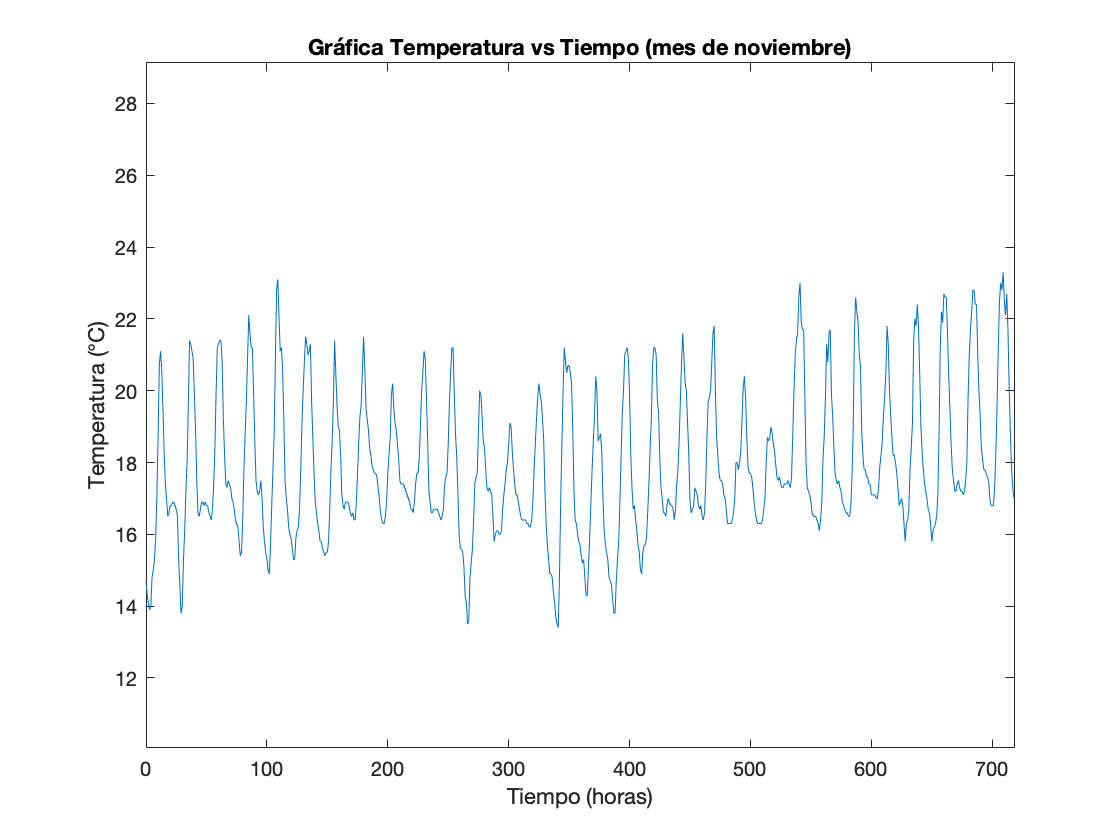

T = CargarData('data.csv');
t = (0:1:length(Tdata)-1);

GraficaGeneral(T, t); hold off;

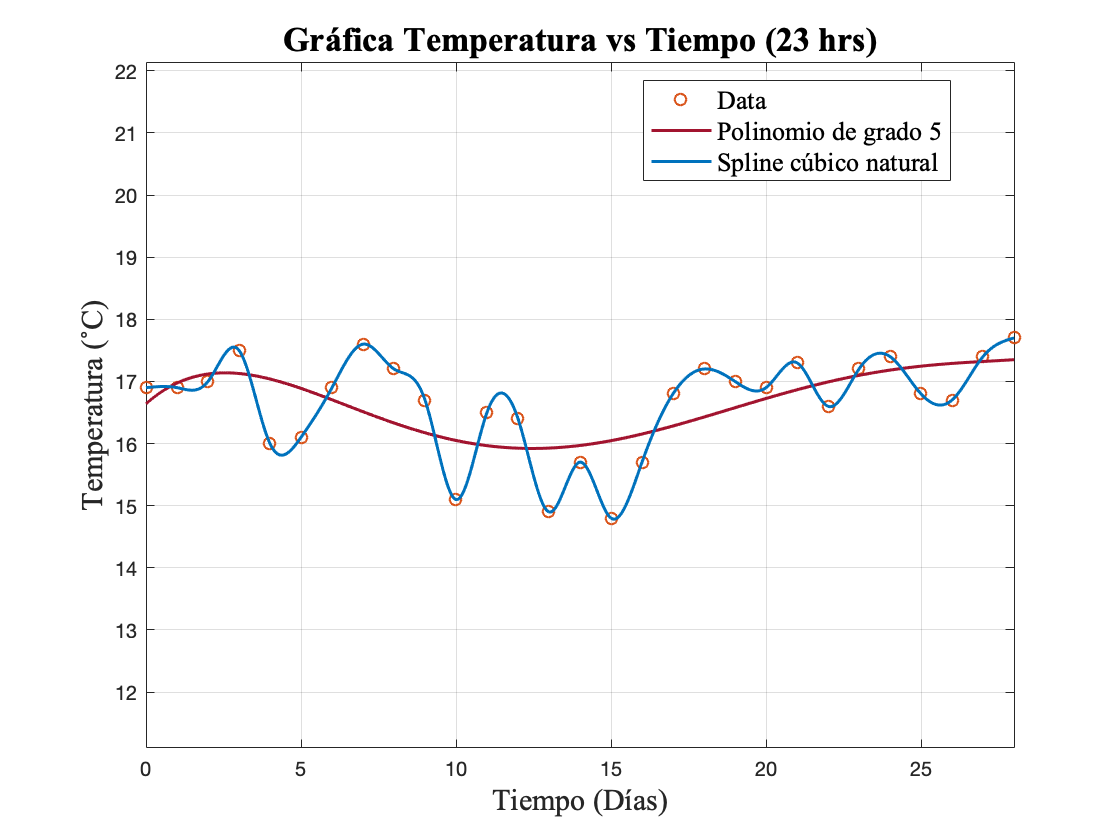

opcion = input('¿Usted tiene conocimiento del proyecto? Sí/No: ', 's');

if strcmp(opcion, 'Sí')
    hora = input("Ingresa la hora del día a analizar (0-23): ");
    grado = input("Ingresa el grado del polinomio aproximante: ");
else
    hora = 12; % Se define por defecto el mediodía
    grado = 3; % Se define por defecto un polinomio de mínimos cuadrados de grado 3
end

[T1, T2] = Grafica(T, hora+1, grado); hold off

disp(T1);

    i     x      y      h[i]    f[x(i),x(i+1)]    S"(x[i]) 
    __    __    ____    ____    ______________    _________

     0     0    16.9      1             0                 0
     1     1    16.9      1           0.1          -0.28658
     2     2      17      1           0.5            1.7463
     3     3    17.5      1          -1.5           -4.2987
     4     4      16      1           0.1            3.4486
     5     5    16.1      1           0.8            0.1042
     6     6    16.9      1           0.7           0.33455
     7     7    17.6      1          -0.4           -2.0424
     8     8    17.2      1          -0.5             1.235
     9     9    16.7      1          -1.6           -3.4977
    10    10    15.1      1           1.4            6.1559
    11    11   

disp(T2);

    i     (x-x[i])        a            b            c         d       [x(i), x(i+1)]  
    __    ________    _________    _________    _________    ____    _________________

     0    "(x-0)"     -0.047764            0     0.047764    16.9    "si x ∈ [0, 1]"  
     1    "(x-1)"       0.33882     -0.14329    -0.095528    16.9    "si x ∈ [1, 2]"  
     2    "(x-2)"       -1.0075      0.87317      0.63435      17    "si x ∈ [2, 3]"  
     3    "(x-3)"        1.2912      -2.1494     -0.64186    17.5    "si x ∈ [3, 4]"  
     4    "(x-4)"       -0.5574       1.7243      -1.0669      16    "si x ∈ [4, 5]"  
     5    "(x-5)"       0.03839     0.052102      0.70951    16.1    "si x ∈ [5, 6]"  
     6    "(x-6)"      -0.39616      0.16727      0.92888    16.9

function [T1, T2] = Grafica(T, hora, grado)
    
    T = T(hora:24:end);
    t = (0:1:length(T)-1);
    
    P = polyfit(t, T, grado);
    tt = linspace(0, length(t)-1, 1000);
    Pt = polyval(P, tt);
    
    % Gráfica de la data
    plot(t, T, 'o', "Color", '#D95319', "LineWidth", 1)
    grid on, hold on
    
    % Gráfica del polinomio de mínimos cuadrados
    plot(tt, Pt, "Color", '#A2142F', "LineWidth", 1.5)
    
    % Gráfica del Spline Cúbico Natural
    [T1, T2] = SplineCubicoNatural(t, T, '#0072BD');
    
    xlim([min(t)     max(t)    ])
    ylim([3/4*min(T) 5/4*max(T)])
    hold off
    
    legend(...
        "Data", ...
        "Polinomio de grado " + int2str(grado), ...
        "Spline cúbico natural", ...
        "Location", "best", ...
        "FontSize", 13, ...
        "FontName", "Times New Roman")
    
    xlabel(...
        "Tiempo (Días)", ...
        "FontSize", 15, "FontName", "Times New Roman")
    
    ylabel(...
        "Temperatura (˚C)", ...
        "FontSize", 15, "FontName", "Times New Roman" )
    
    title(...
        "Gráfica Temperatura vs Tiempo (" + int2str(hora-1) + " hrs)", ...
        "FontSize", 17, "FontName", "Times New Roman")
    
end